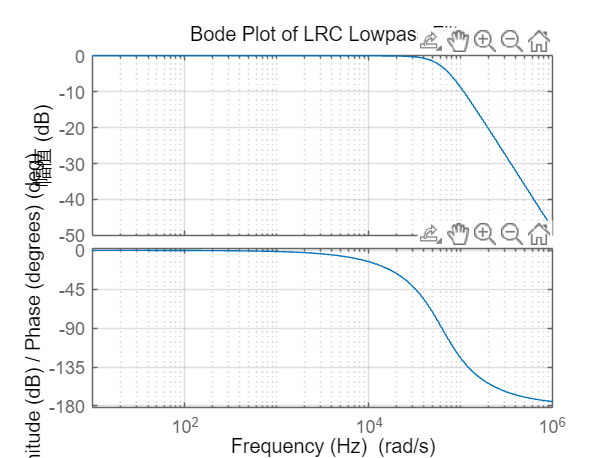

% % 定义 RC 滤波器参数
% R = 1000; % 电阻值，单位：欧姆
% C = 1e-6; % 电容值，单位：法拉
% 
% % 生成频率范围
% w = logspace(1, 6, 1000); % 从 10 到 10^6 rad/s，共 1000 个点
% s = 1j*w;
% 
% % 计算传递函数
% H = 1./(1 + s*R*C);
% 
% % 计算幅值和相位
% magnitude = 20*log10(abs(H)); % 幅值，单位：dB
% phase = angle(H)*180/pi; % 相位，单位：度
% 
% % 绘制 Bode 图
% figure;
% 
% % 绘制幅值响应
% subplot(2,1,1);
% semilogx(w, magnitude);
% grid on;
% title('RC 低通滤波器 Bode 图 - 幅值响应');
% xlabel('角频率 (rad/s)');
% ylabel('幅值 (dB)');
% 
% % 绘制相位响应
% subplot(2,1,2);
% semilogx(w, phase);
% grid on;
% title('RC 低通滤波器 Bode 图 - 相位响应');
% xlabel('角频率 (rad/s)');
% ylabel('相位 (度)');


% 定义截止频率（Hz）
fc = 10000;
% 转换为角频率（rad/s）
wc = 2*pi*fc;

% 选择合适的电感、电阻和电容值
% 对于二阶低通滤波器，截止频率 wc = 1 / sqrt(L * C)
% 假设品质因数 Q = 0.707（巴特沃斯滤波器），Q = 1 / (R * sqrt(C / L))
L = (22/6)*1E-6;
C = 1/(wc^2 * L);
R = 1/(0.707 * sqrt(C / L));

% 定义传递函数的分子和分母系数
num = 1;
den = [L*C, R*C, 1];

% 创建传递函数对象
sys = tf(num, den);

% 生成频率范围
w = logspace(1, 6, 500); % 从 10 Hz 到 1 MHz

% 绘制伯德图
bode(sys, w);
grid on;
title('Bode Plot of LRC Lowpass Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB) / Phase (degrees)');